# Create Building Model With Solar Load

Copyright 2024 - 2025 The MathWorks, Inc.

This project shows how to define a building's floor plan by starting with the layout and definition of individual rooms. In this project, a building consists of multiple apartments, each containing various rooms such as a living room, kitchen, bathroom, and bedroom. A single building can contain several apartments. The orientation of the floor plan of an apartment must be defined in reference with global directions: North (N), East (E), South (S), and West (W). The project uses specific convention to indicate directions on a 2D plot. This workflow guides you through orienting your floor plan in the desired direction and adding windows and vents to the external walls.

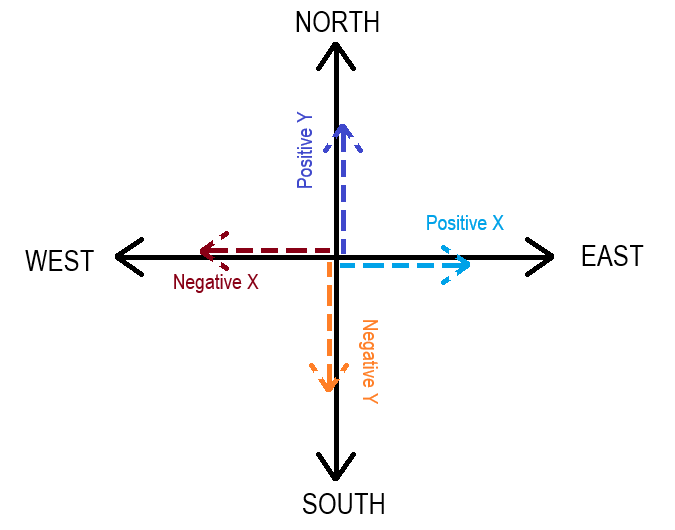

Once your floor plan is prepared, you will construct a 3D building by extending the floor plan in the z-direction, or the vertical axis. All of the windows and vents on a particular wall are uniform in size across the different floor levels. This process is illustrated in the diagram below and described in detail in the following sections.

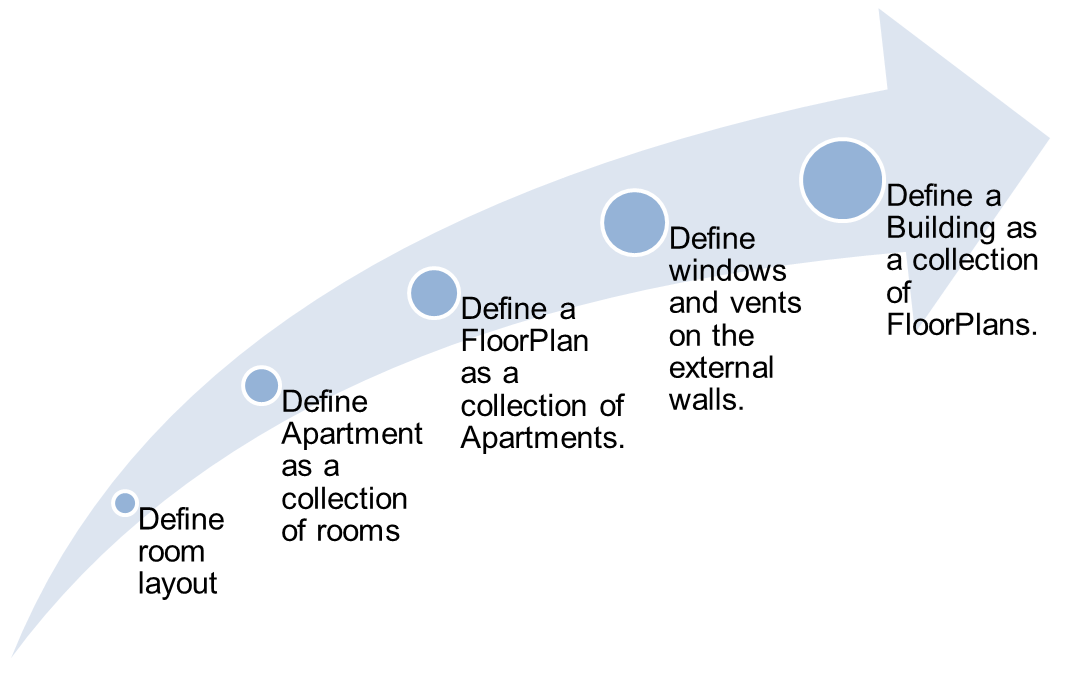

## Create Building

### Define Rooms

Use the function `addRoomToFloorPlan()` to add the room to the apartment unit. See [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')) for more details on the function.

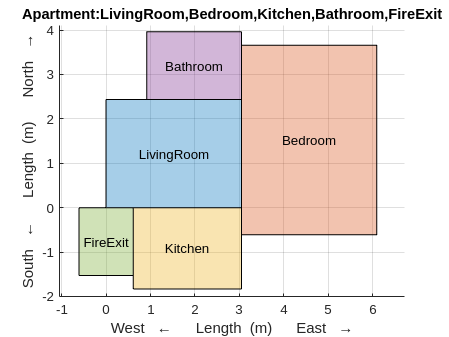

% Initialize a data struct for one apartment unit.
oneAptUnit  = []; 

% Living Room
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="LivingRoom",...
                                  Vertex=simscape.Value([0,0],'ft'),...
                                  Length=simscape.Value(8,'ft'),...
                                  Width=simscape.Value(10,'ft'));

% Bedroom
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Bedroom",...
                                  Vertex=simscape.Value([10,-2],'ft'),...
                                  Length=simscape.Value(14,'ft'),...
                                  Width=simscape.Value(10,'ft'));
% Kitchen
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Kitchen",...
                                  Vertex=simscape.Value([2,-6],'ft'),...
                                  Length=simscape.Value(6,'ft'),...
                                  Width=simscape.Value(8,'ft'));
% Bathroom
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="Bathroom",...
                                  Vertex=simscape.Value([3,8],'ft'),...
                                  Length=simscape.Value(5,'ft'),...
                                  Width=simscape.Value(7,'ft'));

% FireExit
oneAptUnit   = addRoomToFloorPlan(FloorPlan=oneAptUnit,...
                                  NewRoom="FireExit",...
                                  Vertex=simscape.Value([-2,-5],'ft'),...
                                  Length=simscape.Value(5,'ft'),...
                                  Width=simscape.Value(4,'ft'),...
                                  Plot=true);

### Define Apartment

Define one apartment unit.

modelApt = defineSingleApartmentUnit(Apartment=oneAptUnit,...
                                     Tol=0.01);

clear room oneAptUnit

You can use the `copyMoveRotateForNewApartment` function to duplicate the apartment by either moving it a specified distance or rotating it. The following code keeps the apartment stationary but rotates it by 15 degrees around *Bedroom*'s vertex.

apartment  = copyMoveRotateForNewApartment(Apartment=modelApt,...
                                           MoveDistance=simscape.Value([0,0],'ft'),...
                                           RotationAngle=simscape.Value(15,'deg'),...
                                           RotateAboutRoom="Bedroom",...
                                           Tol=0.01);

### Modify Apartment Walls

The `defineSingleApartmentUnit` finds the room to room connectivity automatically. It assumes that all rooms have solid walls between them. To specify a gap or an opening (door, window, or completely remove wall) between two rooms, you must specify the wall fraction value between them. A value of 1 denotes a solid wall between two adjacent rooms while a value of 0 denotes no wall between the two rooms. An intermediate value represents a door or an opening in the wall. 

Display the value of room to room connectivity and associated wall fraction value.

aptTbl = getApartmentRoomConnectivity(Apartment=apartment);
disp(aptTbl);

    #A       RoomA        #B      RoomB       Solid Wall Fraction
    __    ____________    __    __________    ___________________

    1     "LivingRoom"    2     "Bedroom"              1         
    1     "LivingRoom"    3     "Kitchen"              1         
    1     "LivingRoom"    4     "Bathroom"             1         
    1     "LivingRoom"    5     "FireExit"             1         
    2     "Bedroom"       3     "Kitchen"              1         
    2     "Bedroom"       4     "Bathroom"             1         
    3     "Kitchen"       5     "FireExit"             1         



Define the following internal wall openings:

- Add a door between **LivingRoom** and **Kitchen**, with `Solid Wall Fraction` = 0.5.

aptTbl(and(aptTbl.RoomA=="LivingRoom",...
           aptTbl.RoomB=="Kitchen"),:).("Solid Wall Fraction") = 0.5;

- Add a door between **Bedroom** and **Bathroom**, with `Solid Wall Fraction` = 0.75.

aptTbl(and(aptTbl.RoomA=="Bedroom",...
           aptTbl.RoomB=="Bathroom"),:).("Solid Wall Fraction") = 0.75;

- Add a door between **LivingRoom** and **Bedroom**, with `Solid Wall Fraction` = 0.75.

aptTbl(and(aptTbl.RoomA=="LivingRoom",...
           aptTbl.RoomB=="Bedroom"),:).("Solid Wall Fraction") = 0.75;

- Add a door between **LivingRoom** and **FireExit**, with `Solid Wall Fraction` = 0.5.

aptTbl(and(aptTbl.RoomA=="LivingRoom",...
           aptTbl.RoomB=="FireExit"),:).("Solid Wall Fraction") = 0.5;

Update the room connectivity data.

apartment = updateApartmentRoomConnectivity(Apartment=apartment,...
                                            ConnectionTable=aptTbl);

Check the updates made to the connectivity data.

updatedTbl = getApartmentRoomConnectivity(Apartment=apartment);
disp(updatedTbl); clear updatedTbl aptTbl;

    #A       RoomA        #B      RoomB       Solid Wall Fraction
    __    ____________    __    __________    ___________________

    1     "LivingRoom"    2     "Bedroom"            0.75        
    1     "LivingRoom"    3     "Kitchen"             0.5        
    1     "LivingRoom"    4     "Bathroom"              1        
    1     "LivingRoom"    5     "FireExit"            0.5        
    2     "Bedroom"       3     "Kitchen"               1        
    2     "Bedroom"       4     "Bathroom"           0.75        
    3     "Kitchen"       5     "FireExit"              1        



### Define Floorplan

Define the floor plan by consolidating all apartment definitions into a single cell array. The following code defines the floorplan using just one apartment.

floorPlan = defineBuildingFloorPlan(Apartments={apartment});

Plot and visualize the floorplan.

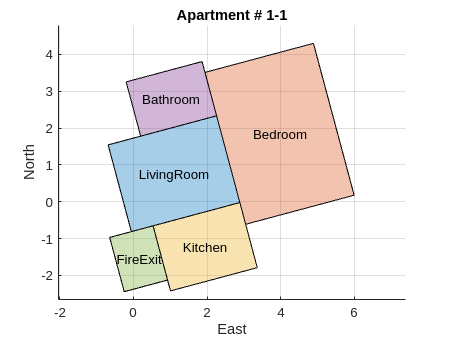

figure('Name','Floor Plan Consolidated');
plotFloorPlanLayout(PlotData=floorPlan,Type="floorplan")

### Modify External Walls

Visualize all the external walls and their identification numbers.

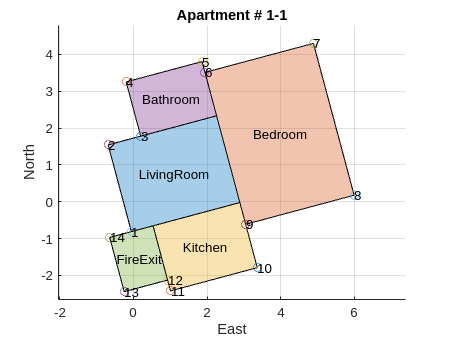

Use function addOpeningOnWallSection() to add windows or vent to the walls.


visualizeBuildingWallsToAddWindowsVents(FloorPlan=floorPlan);

Add windows to a specified set of wall sections. Each row entry below represents a unique wall specification. The first two columns define the wall section indices, while the third column indicates the fraction of the total wall area covered by windows or vents. In this example, walls represented by indices 1-2, 4-5, 7-8, 8-9, and 10-11 have windows with areas specified as 70%, 30%, 70%, 50%, and 70% of the respective wall area.

windowData = [1,2,0.7; ...
              2,3,0.5; ...
              4,5,0.3; ...
              7,8,0.7; ...
              8,9,0.5; ...
              9,10,0.7; ...
              10,11,0.7; ...
              12,13,0.6];

updatedFloorPlan = addOpeningOnWallSection(FloorPlan=floorPlan,...
                                           Data=windowData,...
                                           Type="window");

### Define Building

Set angle to view all 3D plots.

viewingAngle = [-1 -1 1]; 

Generate building 3D model with 3 levels and each level height.

building = generateBuilding3Dlayout(BuildingName="BuildingUnit",...
                                    BuildingFloorPlan=updatedFloorPlan,...
                                    NumberOfLevels=3,...
                                    LevelHeight=simscape.Value(10,'ft'),...
                                    Tol=0.01);

### Modify Building Walls and Floor

Display room connectivity data for the building to update room connectivity in the building.

bldgTbl = getBuildingRoomConnectivity(Building=building);
disp(bldgTbl);

    FlrA    AptA    #A       RoomA        FlrB    AptB    #B       RoomB        Solid Wall Fraction
    ____    ____    __    ____________    ____    ____    __    ____________    ___________________

     1       1      1     "LivingRoom"     1       1      2     "Bedroom"              0.75        
     1       1      1     "LivingRoom"     1       1      3     "Kitchen"               0.5        
     1       1      1     "LivingRoom"     1       1      4     "Bathroom"                1        
     1       1      1     "LivingRoom"     1       1      5     "FireExit"              0.5        
     1       1      2     "Bedroom"        1       1      3     "Kitchen"                 1  

The **FireExit** has stairs and different levels are connected in vertical direction. Update this room connectivity information for all **FireExit** rooms. Find the list of entries where different **FireExit** rooms connect with each other.

listOfEntries = bldgTbl(and(bldgTbl.RoomA=="FireExit",...
                            bldgTbl.RoomB=="FireExit"),:);

Set the `Solid Wall Fraction` value as 0.5.

fireExitWallFrac = 0.5;
bldgTbl(and(bldgTbl.RoomA=="FireExit",...
            bldgTbl.RoomB=="FireExit"),:).("Solid Wall Fraction") = ...
            fireExitWallFrac*ones(size(listOfEntries,1),1);
clear listOfEntries fireExitWallFrac

Update building data struct.

bldg = updateBuildingRoomConnectivity(Building=building,ConnectionTable=bldgTbl);

Check if updates have been applied to the building data.

chkData = getBuildingRoomConnectivity(Building=bldg);
disp(chkData); clear chkData bldgTbl;

    FlrA    AptA    #A       RoomA        FlrB    AptB    #B       RoomB        Solid Wall Fraction
    ____    ____    __    ____________    ____    ____    __    ____________    ___________________

     1       1      1     "LivingRoom"     1       1      2     "Bedroom"              0.75        
     1       1      1     "LivingRoom"     1       1      3     "Kitchen"               0.5        
     1       1      1     "LivingRoom"     1       1      4     "Bathroom"                1        
     1       1      1     "LivingRoom"     1       1      5     "FireExit"              0.5        
     1       1      2     "Bedroom"        1       1      3     "Kitchen"                 1  

Plot building.

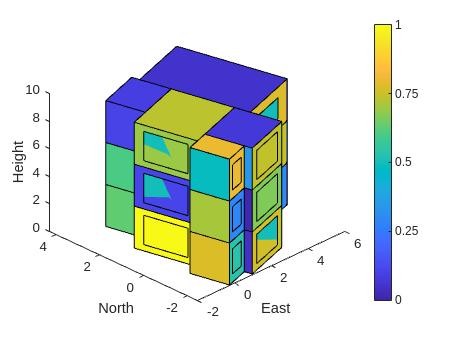

figure('Name','BuildingUnit Elevation');
plot3DlayoutBuilding(Building=building,...
                     PlotViewDirection=viewingAngle,...
                     ColorScheme="random",...
                     InternalWalls=false,...
                     DebugMode=false);

## Define Solar Load on Building

### Evaluate Solar Load

Define the building geographical location. If your location is not included in the list of cities, create a `geoLocation` template and add the necessary data. For more information, see the documentation for function `getGeoLocationForMajorCities` in the [Function Reference List](matlab:open('../Overview/html/FunctionReferenceList.html')).

geoLocation = getGeoLocationForMajorCities(CityName="Vienna");

Specify the datetime duration.

tStart = datetime(2024,1,1,1,0,0); % YYYY,MM,DD,HR,MM,SS
tEnd   = datetime(2024,1,8,1,0,0); % YYYY,MM,DD,HR,MM,SS

Update the building 3D model with solar radiation data on the walls and roof.

[apartment3D,~] = addSolarLoadToBuilding(Building=building,...
                                         Location=geoLocation,...
                                         StartTime=tStart,...
                                         EndTime=tEnd,...
                                         Plot=false,...
                                         PlotColorScheme="radiation");

## Save Building Data

Save the building data with solar radiation load, specified for a given datetime duration, in an XML file. You can load this part file later and use it for analysis.

writeBuildingDataXML(Location=geoLocation,...
                     StartTime=tStart,...
                     EndTime=tEnd,...
                     Building=apartment3D,...
                     FileName='building_with_solar_load.xml');